## Robot Visualizer Example: Object Detection

Copyright 2018 The MathWorks, Inc.

Create a visualizer without trajectory display.

viz = Visualizer2D;
viz.showTrajectory = false;

Create an [`ObjectDetector`](matlab: matlab: edit mrsDocObjectDetector) object and attach it to the map. You can either set the `hasObjDetector`property to `true` and add corresponding object detector parameters, or use the `attachObjectDetector` function.

detector = ObjectDetector;
attachObjectDetector(viz,detector);

Create objects, as a matrix whose rows are `[x, y, label]`. For each possible object label, set a color row `[R, G, B]` (between 0 and 1) to display on the visualizer. 

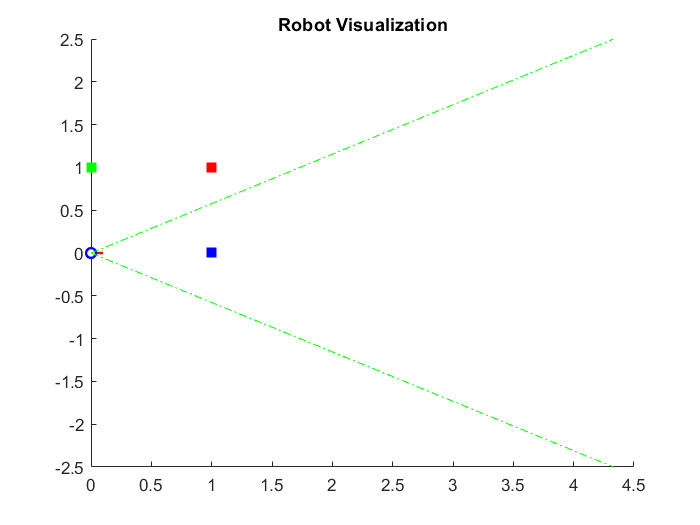

objects = [1, 1, 1; 0, 1, 2; 1, 0, 3]; 
viz.objectColors = [1, 0, 0; 0, 1, 0; 0, 0, 1]; % Red, Green, Blue
pose = [0;0;0];
viz(pose,objects)

Spin the robot in place, simulate the object detector, and view the results.

**NOTE:** If you run this section in a plain code script, this section will be animated.

detections =     1.0000   -0.1963    3.0000

detections =     1.0000   -0.3927    1.0000
    1.4142    0.3927    3.0000

detections =     1.4142    0.1963    1.0000

detections =     1.4142         0    1.0000

detections =     1.4142   -0.1963    1.0000

detections =     1.0000    0.3927    1.0000
    1.4142   -0.3927    2.0000

detections =     1.0000    0.1963    2.0000

detections =      1     0     2

detections =     1.0000   -0.1963    2.0000

detections =     1.0000   -0.3927    2.0000

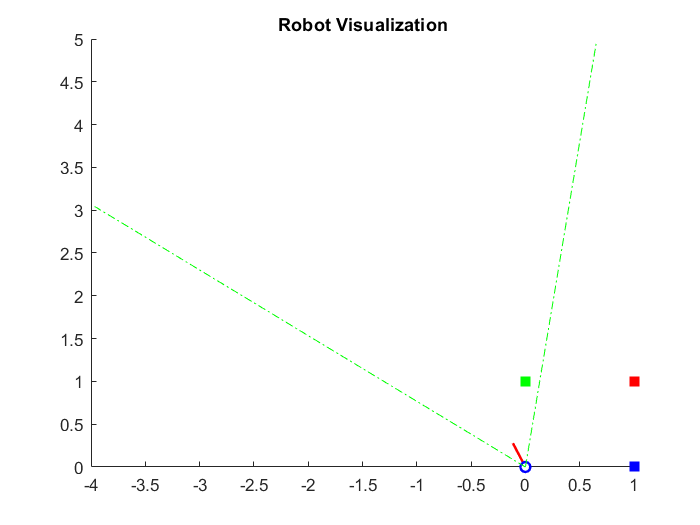

for idx = 1:10
    pose = pose + [0; 0; pi/16];
    detections = detector(pose,objects) % Not needed for pure visualization
    viz(pose,objects)
    pause(0.25)
end